# Evaluate Q-Learning Policy

Compare the results from the Solving Blackjack with Q-Learning example with your expert system AI policy.

## Working directory

Make sure that MATLAB is running in a Current Folder that contains...

- The BlackJackEnv.m file

- Any *.mat files you will be loading.

## Create qtable

The precondition of the script is the results of the `qtable` dictionary that results from running the **blackjack_qlearning.mlx**,  To generate the `qtable` for evaluation you can...

Run the **blackjack_qlearning.mlx** example, or

Load the results from one of the provided .mat files: 

- [blackjack_qlearning_default.mat](https://wiki.nps.edu/download/attachments/1257975273/blackjack_qlearning_default.mat?version=1&modificationDate=1732762232000&api=v2) - Results using the default hyperparameters from the blackjack_qlearning.mlx example.

- [blackjack_qlearning_10x.mat](https://wiki.nps.edu/download/attachments/1257975273/blackjack_qlearning_10x.mat?version=1&modificationDate=1732762296000&api=v2) - Results when increasing the number of episodes by 10x and the decreasing the learning rate by 10x.

load('blackjack_qlearning_default.mat')
%load('blackjack_qlearning_10x.mat')

  Name        Size             Bytes  Class         Attributes

  qtable      1x1             115344  dictionary              



This loads the `qtable` variable in the workspace, which we can validate with...

whos("qtable")

## Policy via action selection

The Q-Learning policy is to select the best (maximum value) action based on the current observation of the game state.

If we use the adaptive $\epsilon$- greedy action selection from the Q-learning demonstration as an example, our action selection function would be simply:

function action = get_action(qtable, observation)
    qc = qtable({observation});
    [maxval, maxi] = max(qc{1});
    action = maxi;
end

## Policy evaluation

We can use the same `evaluate_policy` function from the previous problem, but need to modify it to take the `qtable` as an input.

Specifying a seed:

This is an exention for this solution that was not covered in the assignment, but is meant to illustrate a possible addition.   We've added an optional last argument to specify the [random "seed"](https://www.mathworks.com/help/matlab/ref/rng.html) used in the random number generator. By specifying a specific seed value, we can get a repeatable (but still random) set of numbers to help make comparisons.

function [rewards, mu, conf95] = evaluate_policy(policy_fun, qtable, N, use_seed)
    % EVALUATE_POLICY Function to evaluate a user-specified policy over N hands.
    % Syntax:
    %   rewards = evaluate_policy(policy_fun, N)
    % Inputs:
    %   policy_fun - Function handle to the policy that determines the action
    %                to take given the current observation. The function should
    %                have the signature: 
    %                action = policy_fun(qtable,observation)
    %   qtable     - The q-table as a dictionary to pass to policy_fun
    %   N          - Integer specifying the number of hands to play.
    %
    % Outputs:
    %   rewards    - Nx1 array containing the rewards for each hand played.
    %   mu         - Mean reward for the sample
    %   conf95     - 1x2 array containing the lower and upper 95%
    %   confidence interval.
    %
    % Example:
    %   % Define a simple policy function
    %   policy_fun = @(obs) randi([0, 1]); % Randomly choose action 0 or 1
    %   
    %   % Evaluate the policy over 100 hands
    %   rewards = evaluate_policy(policy_fun, 100);

    
    if nargin < 4
        use_seed = false;
    end
     
    % Initialize the rewards array
    rewards = zeros(N, 1);

    % Intitialize the environment
    if use_seed
        env = BlackJackEnv(1, 42);
    else
        env = BlackJackEnv(1);
    end

    % Loop to play N hands
    for ii = 1:N
        % Reset the environment to start a new hand
        obs = env.reset();
        terminated = false;
        
        % Play the hand until it is done
        while ~terminated
            % Choose an action based on the policy
            action = policy_fun(qtable, obs);
            
            [observation, reward, terminated, truncated, info] = env.step(action);
            
            % Update the observation
            obs = observation;
        end        
        % Accumulate the reward
        rewards(ii) = reward;
    end

    % Calculate reward statistics and print.
    mu = mean(rewards);
    sem = std(rewards)/sqrt(N);
    conf95 = [mu-(1.95*sem), mu+(1.95*sem)];
    fprintf("Mean reward: %.3f, We are 95%% confident that the mean reward is between %.3f and %.3f\n", ...
            mu, conf95(1), conf95(2));

end

Now try it for our `get_action` function handle

[rewards, mu, conf95] = evaluate_policy(@get_action, qtable, 10000)

Mean reward: -0.032, We are 95% confident that the mean reward is between -0.051 and -0.013


rewards =     1.0000
    1.0000
   -1.0000
         0
    1.0000
         0
    1.5000
   -1.0000
   -1.0000
         0


mu = -0.0321

conf95 =    -0.0512   -0.0130


Notice that each time you run this evaluation you get a slighly different value for the performance.

If you want to run the experiment with the same sample of random numbers, you can specify a seed value.  Notice that running this multiple times yields the same results.

[rewards, mu, conf95] = evaluate_policy(@get_action, qtable, 10000, 42)

Mean reward: -0.031, We are 95% confident that the mean reward is between -0.050 and -0.012


rewards =          0
    1.0000
   -1.0000
    1.0000
    1.0000
    1.0000
    1.5000
    1.0000
   -1.0000
    1.0000


mu = -0.0311

conf95 =    -0.0501   -0.0120


## Extension: Comparing datasets

Evaluating multiple datasets.  We ran this for multiple cases and saved that data file.  We'll run this evaluation for each data set.

% Define the data files
datafiles = ["blackjack_qlearning_default.mat", ...
    "blackjack_qlearning_10x.mat", ...
    "blackjack_qlearning_10x_explore_only.mat", ...
    "blackjack_qlearning_100x_explore_only.mat"];

% Initialize arrays for means and confidence intervals
mus = [];
conf95s = [];

% Loop through the data files
for ii = 1:length(datafiles)
    load(datafiles(ii));  % Load each .mat file
    [rewards, mu, conf95] = evaluate_policy(@get_action, qtable, 10000, 42);  % Evaluate policy
    mus(end+1) = mu;  % Store mean
    conf95s(end+1,:) = conf95;  % Store confidence interval
end

Visualize using [errorbar ](https://www.mathworks.com/help/matlab/ref/errorbar.html)plot.

% Calculate error bars (upper and lower bounds)
lowerErrors = mus - conf95s(:,1)';

Mean reward: -0.031, We are 95% confident that the mean reward is between -0.050 and -0.012
Mean reward: -0.023, We are 95% confident that the mean reward is between -0.042 and -0.004
Mean reward: -0.026, We are 95% confident that the mean reward is between -0.045 and -0.007
Mean reward: -0.024, We are 95% confident that the mean reward is between -0.043 and -0.005


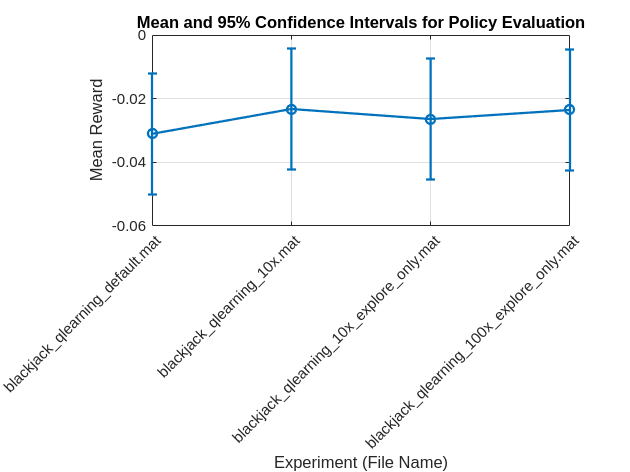

upperErrors = conf95s(:,2)' - mus;

% Create the error bar plot
figure;
errorbar(1:length(mus), mus, lowerErrors, upperErrors, 'o-', 'LineWidth', 1.5);

% Customize the plot
xticks(1:length(datafiles));  % Set x-tick positions
xticklabels(datafiles)  % Set x-tick labels to file names
xtickangle(45);  % Rotate x-tick labels for better readability
xlabel('Experiment (File Name)');
ylabel('Mean Reward');
title('Mean and 95% Confidence Intervals for Policy Evaluation');
grid on;

% Adjust for better display
%set(gca, 'FontSize', 12);  % Set font size for readability
% Set the tick label interpreter to plain text
ax = gca;  % Get current axes
ax.TickLabelInterpreter = 'none';  % Prevent interpretation of underscores